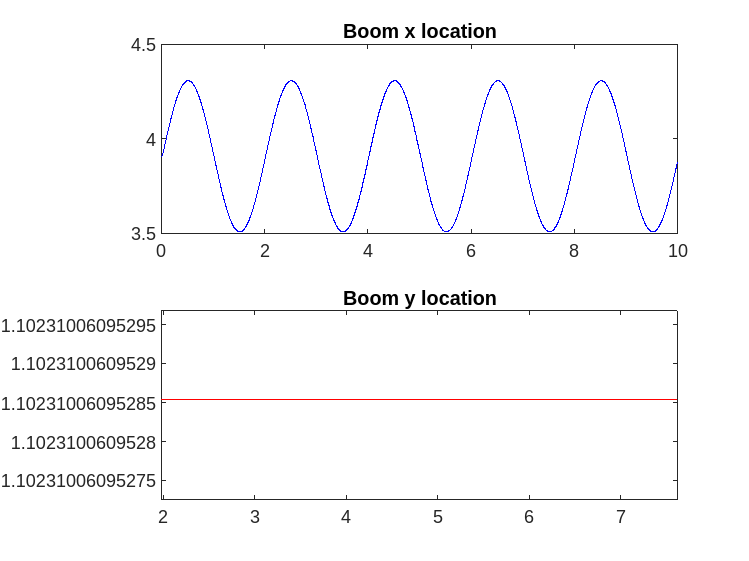

% Assuming your data is in a variable called 'val'
% 'val' is a 3D array with dimensions (M x N x P)

% Specify the color for the plot
line_color = [60 100 175] / 25;

% Define the time vector (assuming 'time' is available)
time = out.boom_x.time;
x_boom = out.boom_x.signals.values;
x_boom = squeeze(x_boom);

y_boom = out.boom_y.signals.values;
y_boom = squeeze(y_boom);

theta1 = out.theta1.Data;
theta1 = squeeze(theta1);

theta2 = out.theta2.Data;
theta2 = squeeze(theta2);

xt2 = out.xt2.Data;
%xt2 = squeeze(xt2);

% Iterate through each slice along the third dimension and plot it

subplot(2,1,1)
plot(time, x_boom, 'color', 'blue')
title("Boom x location")
subplot(2,1,2)
plot(time,y_boom, 'color', 'red')
title("Boom y location")% Create a figure

%Save data into csv file 
%time
%x_boom
%y_boom
fc1 = out.torques.fc1.Data;
fc2 = out.torques.fc2.Data;
fct2 = out.torques.fct2.Data;

all = [time, x_boom, y_boom, theta1, theta2, xt2, fc1, fc2, fct2]

all = 1.0e+05 *

         0    0.0000    0.0000         0         0    0.0000    0.6478    1.3818    0.0000
    0.0000    0.0000    0.0000         0         0    0.0000    0.6476    1.3814    0.0003
    0.0000    0.0000    0.0000         0         0    0.0000    0.6474    1.3810    0.0005
    0.0000    0.0000    0.0000         0         0    0.0000    0.6472    1.3806    0.0008
    0.0000    0.0000    0.0000         0         0    0.0000    0.6471    1.3802    0.0010
    0.0000    0.0000    0.0000         0         0    0.0000    0.6467    1.3794    0.0015
    0.0000    0.0000    0.0000         0         0    0.0000    0.6462    1.3782    0.0023
    0.0000    0.0000    0.0000         0         0    0.0000    0.6455    1.3765    0.0034
    0.0000    0.0000    0.0000         0         0    0.0000    0.6443    1.3739    0.0051
    0.0000    0.0000    0.0000         0         0    0.0000    0.6419    1.3683    0.0086


T = array2table(all);
T.Properties.VariableNames(1:9) = {'time', 'x_boom', 'y_boom', 'theta1', 'theta2', 'xt2', 'fc1', 'fc2', 'fct2'}

T = 10056×9 table
       time       x_boom    y_boom    theta1    theta2    xt2     fc1        fc2           fct2   
    __________    ______    ______    ______    ______    ___    _____    __________    __________

             0    3.9072    1.1023      0         0       0.5    64776    1.3818e+05    9.5757e-14
    3.5963e-06    3.9072    1.1023      0         0       0.5    64758    1.3814e+05        26.054
    7.1926e-06    3.9072    1.1023      0         0       0.5    64741     1.381e+05        52.089
    1.0789e-05    3.9072    1.1023      0         0       0.5    64723    1.3806e+05        78.105
    1.4385e-05    3.9072    1.1023      0         0       0.5    64705    1.3802e

writetable(T, 'testing1.csv');
%writematrix(all, "training_1.csv")


